% Ask the user to select an image
[filename, pathname] = uigetfile({'*.jpg;*.png;*.bmp;*.gif','Image Files (*.jpg, *.png, *.bmp, *.gif)'},'Select an Image');
if isequal(filename, 0)
    disp('No image selected. Exiting.');
    return;
end

% Load the ACF detector
% load('Dataset\ObjectDetection\signs\stop\ACF_Detector_PreCropped_stop.mat');
load("ACF_ODM\ACF_Detector_3CF_HighRes_13S_HR_156x162.mat");

% Read the selected image
selectedImage = imread(fullfile(pathname, filename));

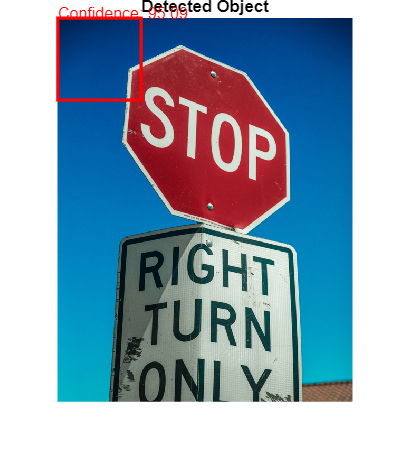


% Process the selected image
[bboxes, scores] = detect(detector, selectedImage, 'Threshold', 1);

% Check if objects are detected
if isempty(bboxes)
    disp('No objects detected.');
else
    % Find the index of the bounding box with the highest confidence score
    [~, idx] = max(scores);

    % Create a figure to display the results
    figure;
    imshow(selectedImage);

    % Display the bounding box with the highest confidence score
    rectangle('Position', bboxes(idx, :), 'EdgeColor', 'r', 'LineWidth', 2);
    text(bboxes(idx, 1), bboxes(idx, 2) - 10, sprintf('Confidence: %4.2f', scores(idx)), 'Color', 'r');

    title('Detected Object');
end